clear

## **Lista de funções:**

r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
f = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*cos(x(1)-(7/5))*cos(x(2)-(9/2));

## Teste 1 - Função matemática g(x)

disp("--------------- Variveis globais --------------");

--------------- Variveis globais --------------


Nvar = 2;
Nmax = randi([35,50])

Nmax = 48

errodf = 15e-2

errodf = 0.1500

NPontosIniciais = randi([8,13])

NPontosIniciais = 13

x_values=[-11;-11]; y_values=[7;7];

disp("------------------- Outputs -------------------");

------------------- Outputs -------------------



PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar, x_values, y_values);
tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_wolfe(g, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste1=toc

tempo_execucao_teste1 = 4.4489

xopt_teste1 = minGlobal(Lopt, g)

xopt_teste1 =    -1.8706
   -1.8706


taxa_media_convergencia_teste1 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste1 = 6.0769

tipo_convergencia_teste1 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste1 = 'Convergência para um mínimo global'

[minimos_locais_teste1, minimizantes_locais_teste1] = minimosMinimizantesLocais(Lopt, g)

minimos_locais_teste1 =    -1.8706   -1.8705   -1.8706
   -1.8713   -1.8701   -1.8706


minimizantes_locais_teste1 =  -141.3956 -141.3956 -141.3956


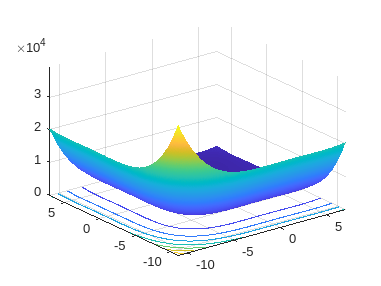

close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

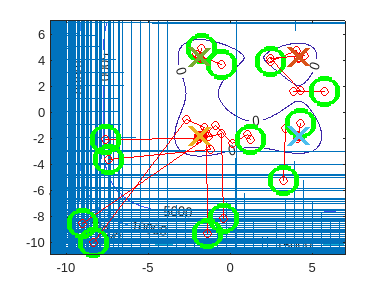


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 2- Função de Rosenbrock

disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_wolfe(r, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste2=toc

tempo_execucao_teste2 = 373.8943

xopt_teste2 = minGlobal(Lopt, r)

xopt_teste2 =     0.6945
    0.4819


taxa_media_convergencia_teste2 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste2 = 48

tipo_convergencia_teste2 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste2 = 'Convergência para um mínimo local'

[minimos_locais_teste2, minimizantes_locais_teste2] = minimosMinimizantesLocais(Lopt, r)

minimos_locais_teste2 =     0.3544    0.4673    0.6945    1.3766
    0.1181    0.2110    0.4819    1.8967


minimizantes_locais_teste2 =     0.4224    0.2892    0.0934    0.1421


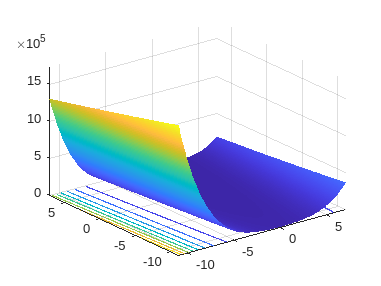

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

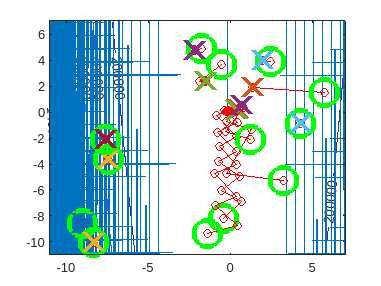


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 3- Função matemática f(x)

disp("---------------------- // ----------------------")

---------------------- // ----------------------



tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_wolfe(f, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste3= toc

tempo_execucao_teste3 = 12.3736

xopt_teste3 = minGlobal(Lopt, f)

xopt_teste3 =    -8.9547
   -4.5479


taxa_media_convergencia_teste3 = taxaMediaConvergencia(LNit)

taxa_media_convergencia_teste3 = 16

tipo_convergencia_teste3 = tipoConvergencia(dffinal, errodf, Nmax)

tipo_convergencia_teste3 = 'Convergência para um mínimo global'

[minimos_locais_teste3, minimizantes_locais_teste3] = minimosMinimizantesLocais(Lopt, f)

minimos_locais_teste3 =    -8.9546   -8.9547   -8.9546    8.9498
   -4.5480   -4.5479   -4.5473    4.5266


minimizantes_locais_teste3 =  -408.7072 -408.7072 -408.7072 -404.8301


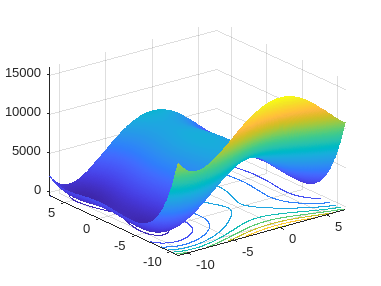

close all

nivelGraficos(f,x_values(1),y_values(1),x_values(2),y_values(2))

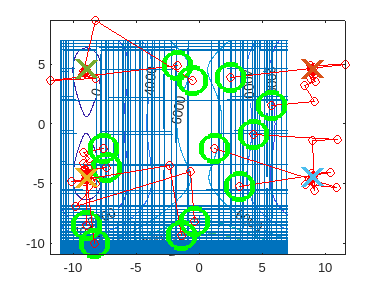


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

T = table([tempo_execucao_teste1; tempo_execucao_teste2; tempo_execucao_teste3], ...
          [taxa_media_convergencia_teste1; taxa_media_convergencia_teste2; taxa_media_convergencia_teste3], ...
          {tipo_convergencia_teste1; tipo_convergencia_teste2; tipo_convergencia_teste3}, ...
          'VariableNames', {'Tempo de Execucao', 'Taxa Media de Convergencia', 'Tipo de Convergencia'}, ...
          'RowNames', {'Teste1', 'Teste2', 'Teste3'});

disp(T);

              Tempo de Execucao    Taxa Media de Convergencia             Tipo de Convergencia         
              _________________    __________________________    ______________________________________

    Teste1         4.4489                    6.0769              {'Convergência para um mínimo global'}
    Teste2         373.89                        48              {'Convergência para um mínimo local' }
    Teste3         12.374                        16              {'Convergência para um mínimo global'}

